# Example 4.6: Monte Carlo Approximations

Note: this script reproduces Example 4.6 (Section 4.3.2) of **Statistics for Chemical Engineers**: Monte Carlo approximations of several quantities as the number of samples S grows. Victor Z UW-Madison, 2020 show convergence of MC approximation

clc; clear all; close all hidden;

## Approximations for different S

generate samples of different sizes and compute approximations for different quantities

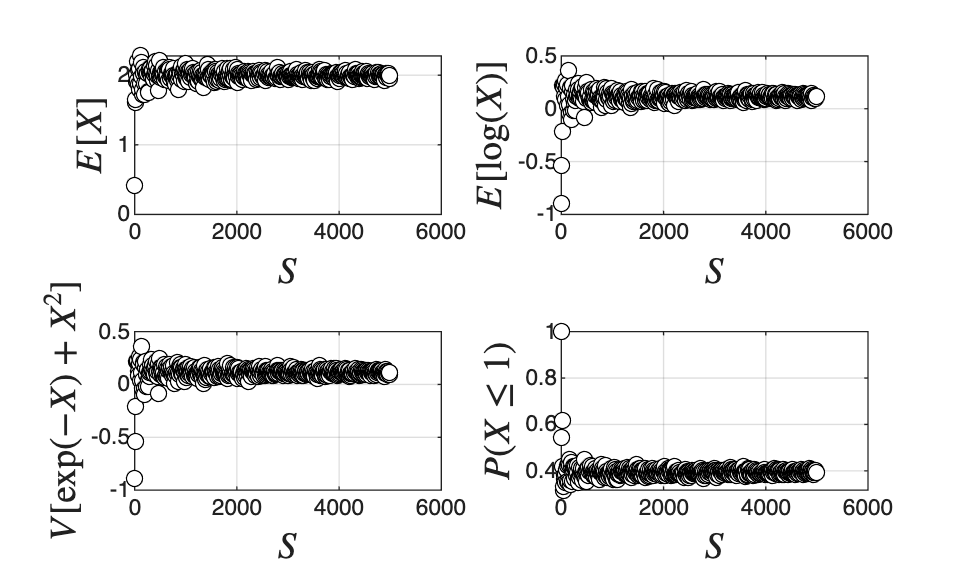

rng(0);
Sv=1:10:5000;
for j=1:length(Sv)
    x = wblrnd(2,1,Sv(j),1);
    e(j) = mean(x);
    v(j) = mean(log(x));
    c(j) = var(exp(x)+x.^2);
    for i=1:Sv(j)
      loc = x<=1;
      prob(j)=sum(loc)/Sv(j);
    end
end

subplot(2,2,1)
plot(Sv,e,'blacko','MarkerFaceColor','w')
ylabel('$E[X]$','Interpreter','latex','FontSize',14)
xlabel('$S$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,2)
plot(Sv,v,'blacko','MarkerFaceColor','w')
ylabel('$E[\log(X)]$','Interpreter','latex','FontSize',14)
xlabel('$S$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,3)
plot(Sv,v,'blacko','MarkerFaceColor','w')
xlabel('$S$','Interpreter','latex','FontSize',14)
ylabel('${V}[\exp(-X)+X^2]$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,4)
plot(Sv,prob,'blacko','MarkerFaceColor','w')
xlabel('$S$','Interpreter','latex','FontSize',14)
ylabel('${P}(X\leq 1)$','Interpreter','latex','FontSize',14)
grid on

print -depsc ch4_convergence_mc.eps

## Note

As in the book, the approximations are unstable for small samples (S below about 100) and become increasingly accurate as S grows (law of large numbers).